intv = 100;
x = -1:1/intv:1; y = x; n = length(x);
c = ones(n,1)/n;
r = pdf('Normal',y,0,1)'; r = r/sum(r);
X0 = r*c';
C = zeros(n,n);
for i = 1:n
    for j = 1:n
        C(i,j) = (y(i)-x(j))^2;
    end
end

## Optimal solution

f = reshape(C,[n^2,1]);
x_vec = reshape(X0,[n^2,1]);
A = zeros(2*n,n^2);
for i = 1:n
    A(1:n,(i-1)*n+1:i*n) = eye(n);
    A(n+i,(i-1)*n+1:i*n) = ones(1,n);
end
A = sparse(A);
lb = -x_vec;
tic
options = optimoptions('linprog','Algorithm','dual-simplex','ConstraintTolerance',1e-9,'OptimalityTolerance',1e-10);
[d,val,exitflag,output] = linprog(f,[],[],A,zeros(2*n,1),lb,[],options);

Optimal solution found.



time_global = toc;
x_vec = x_vec + d;
x_opt = x_vec;
X_opt = reshape(x_vec, [n,n]);
f_opt = trace(C'*X_opt);

## Sinkhorn

epsilon = [0.0001,0.001,0.01,0.1];
maxiter = 300000;
time_sink = zeros(maxiter/100 + 1,4);
feas_sink = zeros(maxiter/100 + 1,4);
fval_sink = zeros(maxiter/100 + 1,4);
for num = 1:4
    if num == 1
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X1_sink] = Sinkhorn(r,c,epsilon(num),C,f_opt,maxiter);
    elseif num == 2
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X2_sink] = Sinkhorn(r,c,epsilon(num),C,f_opt,maxiter);
    elseif num == 3
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X3_sink] = Sinkhorn(r,c,epsilon(num),C,f_opt,maxiter); 
    else 
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X4_sink] = Sinkhorn(r,c,epsilon(num),C,f_opt,maxiter);
    end
end

k = 1000, accuracy = 0.048708
k = 2000, accuracy = 0.048708
k = 3000, accuracy = 0.048706
k = 4000, accuracy = 0.048598
k = 5000, accuracy = 0.047498
k = 6000, accuracy = 0.045255
k = 7000, accuracy = 0.042353
k = 8000, accuracy = 0.039933
k = 9000, accuracy = 0.038994
k = 10000, accuracy = 0.03907
k = 11000, accuracy = 0.039323
k = 12000, accuracy = 0.039535
k = 13000, accuracy = 0.039697
k = 14000, accuracy = 0.039822
k = 15000, accuracy = 0.039914
k = 16000, accuracy = 0.039926
k = 17000, accuracy = 0.039756
k = 18000, accuracy = 0.039344
k = 19000, accuracy = 0.038685
k = 20000, accuracy = 0.037807
k = 21000, accuracy = 0.036576
k = 22000, accuracy = 0.03517
k = 23000, accuracy = 0.033963
k = 24000, accuracy = 0.033028
k = 25000, accuracy = 0.032017
k = 26000, accuracy = 0.031368
k = 27000, accuracy = 0.030923
k = 28000, accuracy = 0.030937
k = 29000, accuracy = 0.031045
k = 30000, accuracy = 0.031144
k = 31000, accuracy = 0.031224
k = 32000, accuracy = 0.031226
k = 33000, accuracy

k = 1000, accuracy = 0.041698
k = 2000, accuracy = 0.036638
k = 3000, accuracy = 0.031776
k = 4000, accuracy = 0.028082
k = 5000, accuracy = 0.024503
k = 6000, accuracy = 0.021868
k = 7000, accuracy = 0.019191
k = 8000, accuracy = 0.016897
k = 9000, accuracy = 0.015127
k = 10000, accuracy = 0.013435
k = 11000, accuracy = 0.011802
k = 12000, accuracy = 0.010391
k = 13000, accuracy = 0.0092459
k = 14000, accuracy = 0.0082846
k = 15000, accuracy = 0.0074053
k = 16000, accuracy = 0.0065776
k = 17000, accuracy = 0.0058117
k = 18000, accuracy = 0.0051218
k = 19000, accuracy = 0.0045111
k = 20000, accuracy = 0.0039776
k = 21000, accuracy = 0.0035148
k = 22000, accuracy = 0.0031137
k = 23000, accuracy = 0.0027658
k = 24000, accuracy = 0.0024626
k = 25000, accuracy = 0.0021965
k = 26000, accuracy = 0.0019615
k = 27000, accuracy = 0.001753
k = 28000, accuracy = 0.0015671
k = 29000, accuracy = 0.0014009
k = 30000, accuracy = 0.0012521
k = 31000, accuracy = 0.0011188
k = 32000, accuracy = 0.000999

k = 1000, accuracy = 0.013543
k = 2000, accuracy = 0.0042394
k = 3000, accuracy = 0.0014371
k = 4000, accuracy = 0.00058775
k = 5000, accuracy = 0.00033009
k = 6000, accuracy = 0.0002519
k = 7000, accuracy = 0.00022818
k = 8000, accuracy = 0.00022098
k = 9000, accuracy = 0.00021879
k = 10000, accuracy = 0.00021813
k = 11000, accuracy = 0.00021793
k = 12000, accuracy = 0.00021786
k = 13000, accuracy = 0.00021785
k = 14000, accuracy = 0.00021784
k = 15000, accuracy = 0.00021784
k = 16000, accuracy = 0.00021784
k = 17000, accuracy = 0.00021784
k = 18000, accuracy = 0.00021784
k = 19000, accuracy = 0.00021784
k = 20000, accuracy = 0.00021784
k = 21000, accuracy = 0.00021784
k = 22000, accuracy = 0.00021784
k = 23000, accuracy = 0.00021784
k = 24000, accuracy = 0.00021784
k = 25000, accuracy = 0.00021784
k = 26000, accuracy = 0.00021784
k = 27000, accuracy = 0.00021784
k = 28000, accuracy = 0.00021784
k = 29000, accuracy = 0.00021784
k = 30000, accuracy = 0.00021784
k = 31000, accuracy = 0.

k = 1000, accuracy = 0.0022921
k = 2000, accuracy = 0.0022918
k = 3000, accuracy = 0.0022918
k = 4000, accuracy = 0.0022918
k = 5000, accuracy = 0.0022918
k = 6000, accuracy = 0.0022918
k = 7000, accuracy = 0.0022918
k = 8000, accuracy = 0.0022918
k = 9000, accuracy = 0.0022918
k = 10000, accuracy = 0.0022918
k = 11000, accuracy = 0.0022918
k = 12000, accuracy = 0.0022918
k = 13000, accuracy = 0.0022918
k = 14000, accuracy = 0.0022918
k = 15000, accuracy = 0.0022918
k = 16000, accuracy = 0.0022918
k = 17000, accuracy = 0.0022918
k = 18000, accuracy = 0.0022918
k = 19000, accuracy = 0.0022918
k = 20000, accuracy = 0.0022918
k = 21000, accuracy = 0.0022918
k = 22000, accuracy = 0.0022918
k = 23000, accuracy = 0.0022918
k = 24000, accuracy = 0.0022918
k = 25000, accuracy = 0.0022918
k = 26000, accuracy = 0.0022918
k = 27000, accuracy = 0.0022918
k = 28000, accuracy = 0.0022918
k = 29000, accuracy = 0.0022918
k = 30000, accuracy = 0.0022918
k = 31000, accuracy = 0.0022918
k = 32000, accura

## Accelerated RBCD

maxiter = 5000;
M = 40;
[fval_arbcd,time_arbcd,feas_arbcd,X2,card_arbcd]=ARBCD(r,c,n,X1,f_opt,C,M,maxiter,1);

iter = 1000, accuracy = 1.4007e-05
iter = 2000, accuracy = 3.2508e-06
iter = 3000, accuracy = 8.3319e-07
iter = 4000, accuracy = 7.0541e-07
iter = 5000, accuracy = 6.6905e-09
number of successful iterations =4934


## Transportation plan

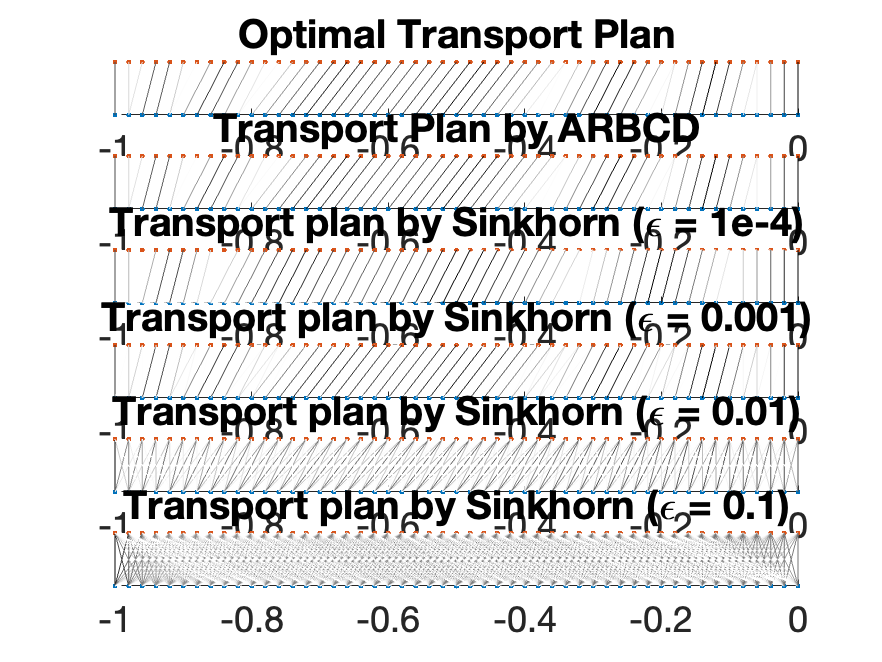

ind = 1:2:101;
l = length(ind);
list = {X_opt,X2,X1_sink,X2_sink,X3_sink,X4_sink};
titlelist = {'Optimal Transport Plan','Transport Plan by ARBCD',...
    'Transport plan by Sinkhorn (\epsilon = 1e-4)',...
    'Transport plan by Sinkhorn (\epsilon = 0.001)',...
    'Transport plan by Sinkhorn (\epsilon = 0.01)',...
    'Transport plan by Sinkhorn (\epsilon = 0.1)'};
figure()
for k = 1:6
ff=list{k}(ind,ind);
[xx1,xx2]=meshgrid(x(ind),y(ind));
[yy1,yy2]=meshgrid(zeros(1,l),ones(1,l));
xx1=xx1(:);
yy1=yy1(:);
xx2=xx2(:);
yy2=yy2(:);
ff=ff(:);
ff = max(0,ff);
ff = ff/max(ff);
subplot(6,1,k);
scatter(x(ind),zeros(1,l),'.');
hold on
scatter(y(ind),ones(1,l),'.');
set(gca,'YColor',[1 1 1]);
title(titlelist{k})
set(gca,'FontSize',18)
for i = 1:length(xx1)
    if ff(i) > 1e-4
    plot([xx1(i),xx2(i)],[yy1(i),yy2(i)],'Color',[1,1,1]*(1-ff(i)))
    end
end
end
set(gcf,'Innerposition',[200,200,1600,1200])
exportgraphics(gcf,'Transportplans.png','Resolution',500)

## Plot

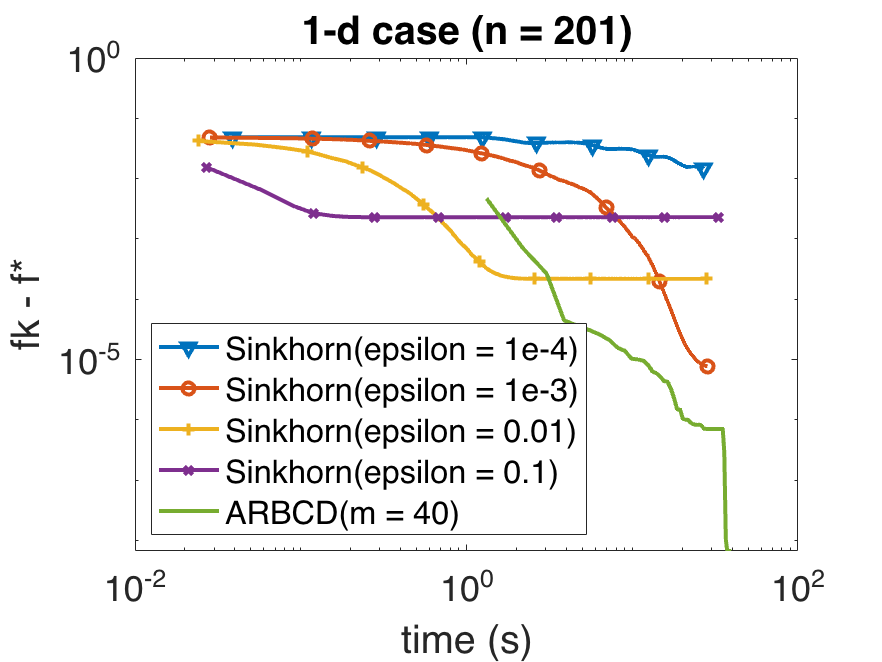

figure
loglog(time_sink(:,1),fval_sink(:,1),'-v','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_sink(:,2),fval_sink(:,2),'-o','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_sink(:,3),fval_sink(:,3),'-+','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_sink(:,4),fval_sink(:,4),'-x','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_arbcd,fval_arbcd,'LineWidth',2)
xlim([1e-2 1e2])
legend('Sinkhorn(epsilon = 1e-4)','Sinkhorn(epsilon = 1e-3)','Sinkhorn(epsilon = 0.01)','Sinkhorn(epsilon = 0.1)','ARBCD(m = 40)','location','southwest')
title('1-d case (n = 201)')
xlabel('time (s)')
ylabel('fk - f*')
set(gca,'FontSize',18)